
clear;clc;
% this is E0
a = [1 2 3];
a = [1, 3, 4];

b = a.^2;
c = [7, 8 ,9];
d = a .* c; % a times c
f = c ./ a;

i = [.09 .21 0.30 0.42];
v = [2.00 3.80 6.12 8.32];
% V vs. i 

plot(i, v, '*'); hold on; % hold on combines two sets of data into one graph
%plot(i,V)
% do NOT plot exp data as line


xlabel('current i (A)');
ylabel('Voltage V (volt)');
title('Voltage V vs. current i');
%hold off;

i1 = [.06, .24,.34, .45];
v1 = [2.1 3.7 6.0 8.9];
plot(i1, v1, 'x');

R = v./i;

resAvg = mean(R); % mean of resistance
sigR = std(R); % standard deviation of R

%linear regression formula
p = polyfit(i, v , 1);
Rmean = p(1); % slope value
R_intercept = p(2); % intercept value




%page 3 
n = length(i);
epsilon = sqrt(sum((v-p(1)*i - p(2)).^2)/(n-2));
delta = n*sum(i.^2) - (sum(i)) ^2;
sigmaa = sqrt(n*epsilon^2/delta);

# 1.3253

sigmab = sqrt(epsilon^2*sum(i.^2)/delta);
hold on;
plot(i, p(1)*i+p(2), '-');



%length and sum
s1 = [12 34 5 6 7 8 9 102];
n = length(s1); % total count of variables

sumVal = sum(s1);


x1 = v - p(1)*i - p(2) % array with 4 elements

x1 =     0.1757   -0.3775    0.1775    0.0243


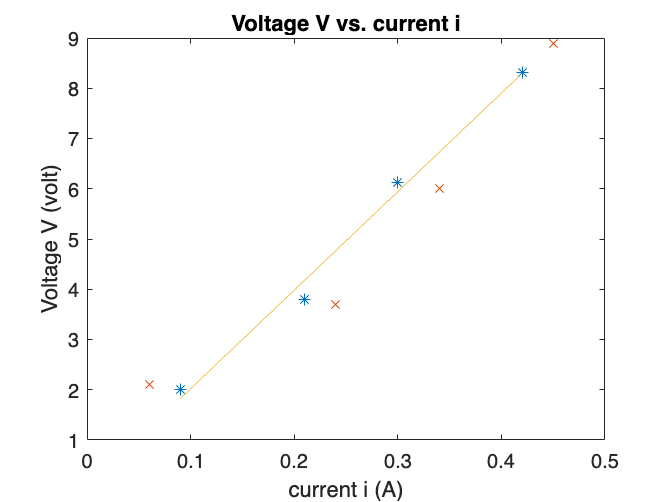

% epsilon step by step

x2 = x1.^2; %square of the matrix
x3 = sum(x2); % sum over deviation square
ep2 = x3/(n-2); %epsilon square
ep1 = sqrt(ep2);

%delta step by step

y1 = n*sum(i.^2);
y2 = (sum(i))^2;
deltaq = y1 - y2;


%linear plot of exponential decay
t = [0 1 2 3 4 5 6 7];
v = [3.2 2.3 1.4 0.9 0.6 0.4 0.27 0.15];
nt = length(t);
nv = length(v);
hold off

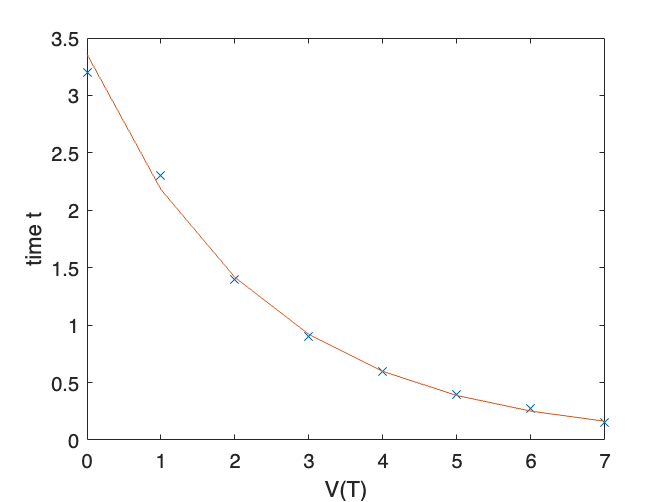

plot(t,v, 'x'); hold on


p = polyfit(t, log(v), 1);
tauVal = -1/p(1);
V0 = exp(p(2));
plot(t, V0*exp(-t/tauVal), '-');
xlabel('V(T)');
ylabel('time t');
hold off

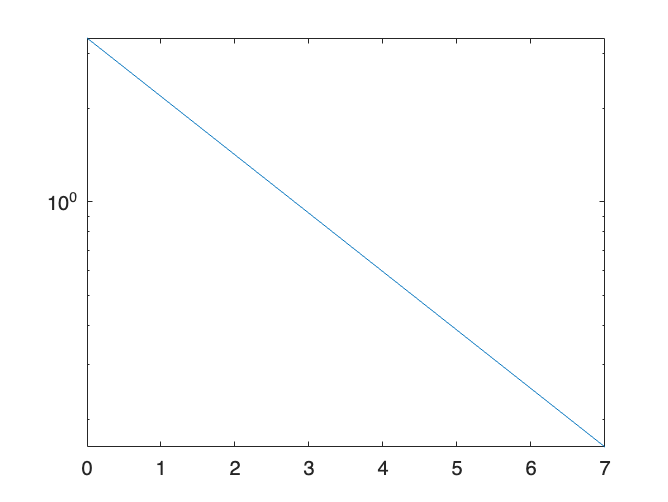


p = polyfit(t, log(v), 1);
tauVal = -1/p(1);
V0 = exp(p(2));

%add fit to semilogy plot
semilogy(t, V0*exp(-t/tauVal), '-');


g = 4*pi^2*1.59^2*0.1;

sigg = sqrt((8*pi^2*1.59*0.1*.03)^2 +(4*pi^2*1.59^2*1e-3)^2)

sigg = 0.3896